close('all'); clear; clc;

% C = StraightSegment(100);
% C.Rotate(-20)
% disp(C);
% C.Plot()

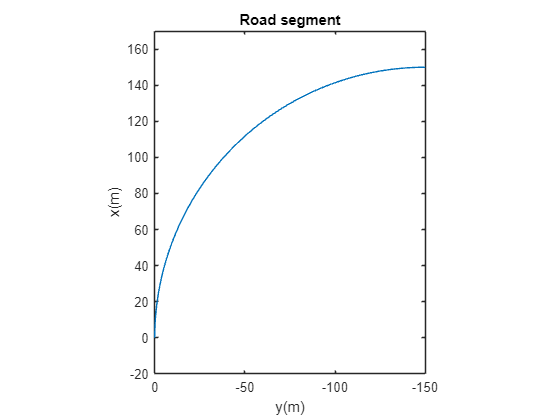

r = 150;
ang_a = deg2rad(90);
C = ArcSegment(r*ang_a,r,"right");
plot(C);

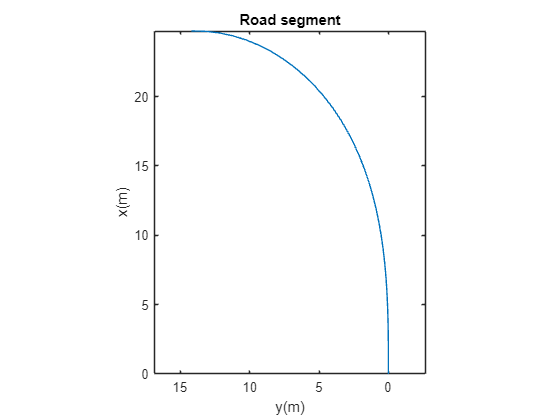

C = ClothoidSegment(32,inf,10,"left");
plot(C);

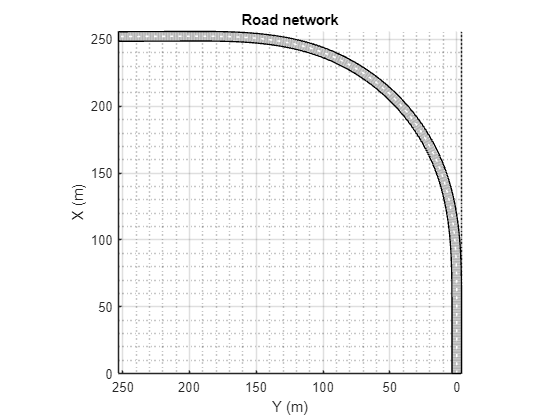

R = Road();
ra = 150;
ang = deg2rad(52);
R.addStraight(50);
R.addClothoid(100,inf,ra,"left");
R.addArc(ra*ang,ra,"left");
R.addClothoid(100,ra,inf,"left");
R.addStraight(50);
plot(R);

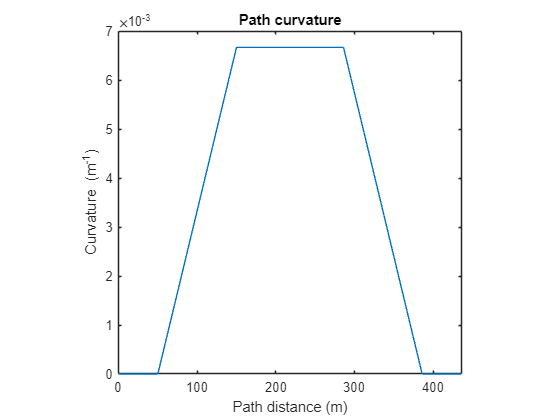

figure();
Distance = linspace(0,R.Length,length(R.Curvature));
plot(Distance,R.Curvature);
xlim([0,R.Length]);
xlabel('Path distance (m)');
ylabel('Curvature (m^{-1})');
title('Path curvature');
axis('square');